# Experiment Set #38.

The goal of the experiment is to identify how robust optimization can be done to find minimal zonotope representation.

% Add experiments and functions to the path
include_fcns('MPT3','YALMIP')

Creating a set that we want to enclose with an arbitrary zonotope.

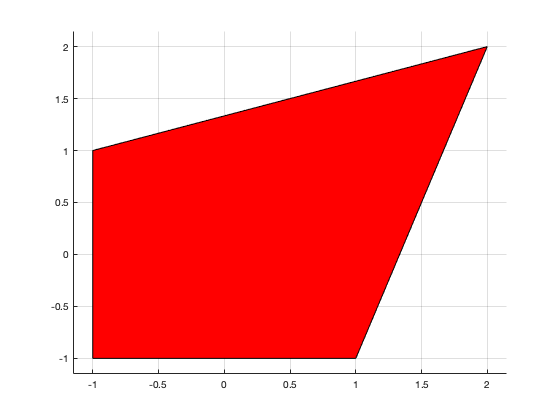

P_e = Polyhedron('A', [ 0 , -1; -1, 0; -(1/3), 1; 3, -1 ], ...
                 'b', [1;1;(4/3);4]);
figure;
plot(P_e)

Create a zonotope template. We will control the scaling of the generators to control its size in optimization. A traditional zonotope might be:


$$$\mathcal{Z} = \left\{ x \in \mathbb{R}^2 \left| \exists \theta \; \text{ s.t. } x = c + G\theta \wedge (|\theta_i| \leq 1 \; \forall i) \right. \right\}$
$$


And so we seek to find a modified zonotope of the following form:


$$$\mathcal{Z}_{\alpha} = \left\{ x \in \mathbb{R}^2 \left| \exists \theta \; \text{ s.t. } x = c + G\theta \wedge (|\theta_i| \leq \alpha \; \forall i) \right. \right\}$
$$


Z_t.c = zeros(2,1);
%Z_t.G = [ [1;0] [0;1] ];
%Z_t.G = [ [1;1]*(1/sqrt(2)), [0;1] ]
Z_t.G = [ [2;2], [1;-1] ]

Z_t = struct with fields:
    c: [2×1 double]
    G: [2×2 double]


With all of this, we can state the formal problem that we want to solve:


$$\begin{array}{rl}
  \underset{\alpha}{\text{min}} & \alpha \\
  \text{subject to} & \mathcal{P}_w \subseteq \mathcal{Z}_{\alpha}
\end{array} $$


This can be stated in the following way:


$$\begin{array}{rl}
  \underset{\begin{array}{c} \alpha \in \mathbb{R} \end{array}}{\text{min}} & \alpha \\
  \text{subject to} & \exists \theta \text{ such that } w = c + G \theta \text{ for any } w \in \mathcal{P}_w
\end{array} $$


In a more mathematical construction:


$$\begin{array}{rll}
  \underset{\alpha \in \mathbb{R}, \; \theta \in \mathbb{R}^2}{\text{min}} & \alpha & \\
  \text{subject to} & | \theta_i | \leq 1 & \forall i \in {1,2} \\ & w = c +\alpha G \theta & \forall w \in \mathcal{P}_w
\end{array} $$


This is in fact a robust optimization problem and I think that we can apply the following robust optimization to solve the problem:


$$\begin{array}{rll}
  \underset{\alpha \in \mathbb{R}, }{\text{min}} & \alpha & \\
  \text{subject to} & | \theta_i | \leq \alpha & \forall i \in {1,2} \\ & w \preceq c +G \theta & \forall w \in \mathcal{P}_w \\
  & -w \preceq -c - G \theta & \forall w \in \mathcal{P}_w
\end{array} $$


This can be written in the following optimization by considering every element-wise inequality in the two generalized inequalities above:


$$\begin{array}{rll}
  \underset{\alpha \in \mathbb{R}, \; \theta^{(1)},\theta^{(2)} \in \mathbb{R}^2}{\text{min}} & \alpha & \\
  \text{subject to} & | \theta_i^{(j)} | \leq \alpha & \forall i,j \in {1,2} \\
 & \left[
             \begin{array}{rll}
                \underset{w\in P_w}{\text{max}} &  (G^\dagger)_i w &  \\
                \text{such that} & Aw \leq b
             \end{array}
     \right] \leq (G^{\dagger})_i c + \theta^{(1)}_i & \forall i \in [1,n_z] \\
 & \left[
             \begin{array}{rll}
                \underset{w\in P_w}{\text{max}} &  -(G^\dagger)_i w &  \\
                \text{such that} & Aw \leq b
             \end{array}
     \right] \leq -(G^{\dagger})_i c - \theta^{(2)}_i & \forall i \in [1,n_z] \\\end{array} $$


where the $(G^\dagger)_i$ indicates the $i^{th}$ row of the pseudoinverse of $G$, and $n_z$ is the dimension of the zonotope. To better fit this into the paradigm of robust linear programming, we take a transpose of the objective in the constraints:


$$\begin{array}{rll}
  \underset{\alpha \in \mathbb{R}, \; \theta^{(1)},\theta^{(2)} \in \mathbb{R}^2}{\text{min}} & \alpha & \\
  \text{subject to} & | \theta_i^{(j)} | \leq \alpha & \forall i,j \in {1,2} \\
 & \left[
             \begin{array}{rll}
                \underset{w\in P_w}{\text{max}} &  w^\top ((G^\dagger)_i)\top &  \\
                \text{such that} & Aw \leq b
             \end{array}
     \right] \leq (G^{\dagger})_i c + \theta^{(1)}_i & \forall i \in [1,n_z] \\
 & \left[
             \begin{array}{rll}
                \underset{w\in P_w}{\text{max}} &  -w^\top ((G^\dagger)_i)^\top &  \\
                \text{such that} & Aw \leq b
             \end{array}
     \right] \leq -(G^{\dagger})_i c - \theta^{(2)}_i & \forall i \in [1,n_z] \\\end{array} $$


By introducing dual variables, the problem becomes:


$$\begin{array}{rll}
  \underset{
    \begin{array}{c}
      \alpha \in \mathbb{R}, \\
      \theta^{(1)},\theta^{(2)} \in \mathbb{R}^2, \\
      \pi^{(1)}_i,\pi^{(2)}_i \in \mathbb{R} \quad \forall i \in [1,n_z]
    \end{array}}
    {\text{min}} & \alpha & \\
  \text{subject to} & | \theta_i^{(j)} | \leq \alpha & \forall i,j \in \{1,2 \} \\
 & \left[
             \begin{array}{rll}
                \underset{w\in P_w}{\text{"min"}} &  (\pi^{(1)}_i)^\top b &  \\
                \text{such that} & A^\top \pi^{(1)}_i = ((G^\dagger)_i)^\top \\
                                         & \pi^{(1)}_i \succeq 0
             \end{array}
     \right] \leq (G^{\dagger})_i c + \theta^{(1)}_i & \forall i \in [1,n_z] \\
 & \left[
             \begin{array}{rll}
                \underset{w\in P_w}{\text{"min"}} &  (\pi^{(2)}_i)^\top b &  \\
                \text{such that} & A^\top \pi^{(2)}_i = -(G^\dagger)^\top \\
                                         & \pi^{(2)}_i \succeq 0
             \end{array}
     \right] \leq -(G^{\dagger})_i c - \theta^{(2)}_i & \forall i \in [1,n_z]\\ \end{array} $$


Then a final linear program can be presented as:


$$\begin{array}{rll}
  \underset{
    \begin{array}{c}
      \alpha \in \mathbb{R}, \\
      \theta^{(1)},\theta^{(2)} \in \mathbb{R}^2, \\
      \Pi^{(1)}_i,\Pi^{(2)}_i \in \mathbb{R}^{n_w \times n_z}
    \end{array}}
    {\text{min}} & \alpha & \\
  \text{subject to} & | \theta_i^{(j)} | \leq \alpha & \forall i,j \in \{1,2 \} \\
 & (\Pi^{(1)})^\top b \leq G^\dagger c + \theta^{(1)} & \\
 & (\Pi^{(2)})^\top b \leq -(G^{\dagger}) c - \theta^{(2)} & \\
 & A^T \Pi^{(1)} = (G^\dagger)^\top & \\
 & A^T \Pi^{(2)} = -(G^\dagger)^\top & \\
 & \Pi^{(i)} \succeq 0 & \forall i \in \{ 1,2 \} \\
 \end{array} $$


%Define Optimization Variables
alpha = sdpvar(1,1,'full');
theta_t1 = sdpvar(size(Z_t.G,2),1,'full');
theta_t2 = sdpvar(size(Z_t.G,2),1,'full');
Pi1 = sdpvar(size(P_e.A,1),size(theta_t1,1),'full');
Pi2 = sdpvar(size(P_e.A,1),size(theta_t2,1),'full');

%Create Objective
objective = alpha;

%Create Constraints
equal_constrs = [(Pi1)'*P_e.b <= theta_t1 + pinv(Z_t.G)*Z_t.c] + ...
                [(Pi2)'*P_e.b <= -theta_t2 - pinv(Z_t.G)*Z_t.c];
dual_equal_constrs = [];
dual_equal_constrs = [P_e.A'*Pi1 == (pinv(Z_t.G))'] + ...
                     [P_e.A'*Pi2 == (-pinv(Z_t.G))'];
                 
dual_pos_constrs = [Pi1 >= 0] + [Pi2 >= 0];

%
inf_norm_constr = [ theta_t1 <= alpha ] + [-theta_t1 <= alpha] + ...
                  [ theta_t2 <= alpha ] + [-theta_t2 <= alpha];

%Optimize
ops = sdpsettings('verbose',1);
optim0 = optimize(equal_constrs+dual_equal_constrs+dual_pos_constrs+inf_norm_constr, ...
			objective, ...
			ops);

Academic license - for non-commercial use only
Optimize a model with 36 rows, 21 columns and 76 nonzeros
Coefficient statistics:
  Matrix range     [3e-01, 4e+00]
  Objective range  [1e+00, 1e+00]
  Bounds range     [0e+00, 0e+00]
  RHS range        [2e-01, 5e-01]
Presolve removed 29 rows and 10 columns
Presolve time: 0.00s
Presolved: 7 rows, 11 columns, 25 nonzeros

Iteration    Objective       Primal Inf.    Dual Inf.      Time
       0    1.0000000e+00   0.000000e+00   0.000000e+00      0s
       0    1.0000000e+00   0.000000e+00   0.000000e+00      0s

Solved in 0 iterations and 0.01 seconds
Optimal objective  1.000000000e+00


if optim0.problem ~= 0
    disp(['Optimization failed with "problem" value: ' num2str(optim0.problem)])
else
    disp('Optimization seems to have been successful.')
    disp(['alpha = ' num2str(value(alpha))])
end

Optimization seems to have been successful.


alpha = 1



%Optimal Scaling factor
sf = value(alpha)

sf = 1.0000